## Biometric Fusion based Identification (PPG, ECG, SQRT)

from BioMetric_ECG_PPG_SQRT_MDPI_V1.csv the fusion colum values or "SQRT" is taken as input.

The 28,000 rows of signal data is broken into many smaller instances based on window size of the signal frequency "minOneBeat". The inputs are taken into non decimal value to calcluate features [ as pentropy feature could not be calculated from decimal values ]

The loop ensures all the user data is taken into the input matrix.

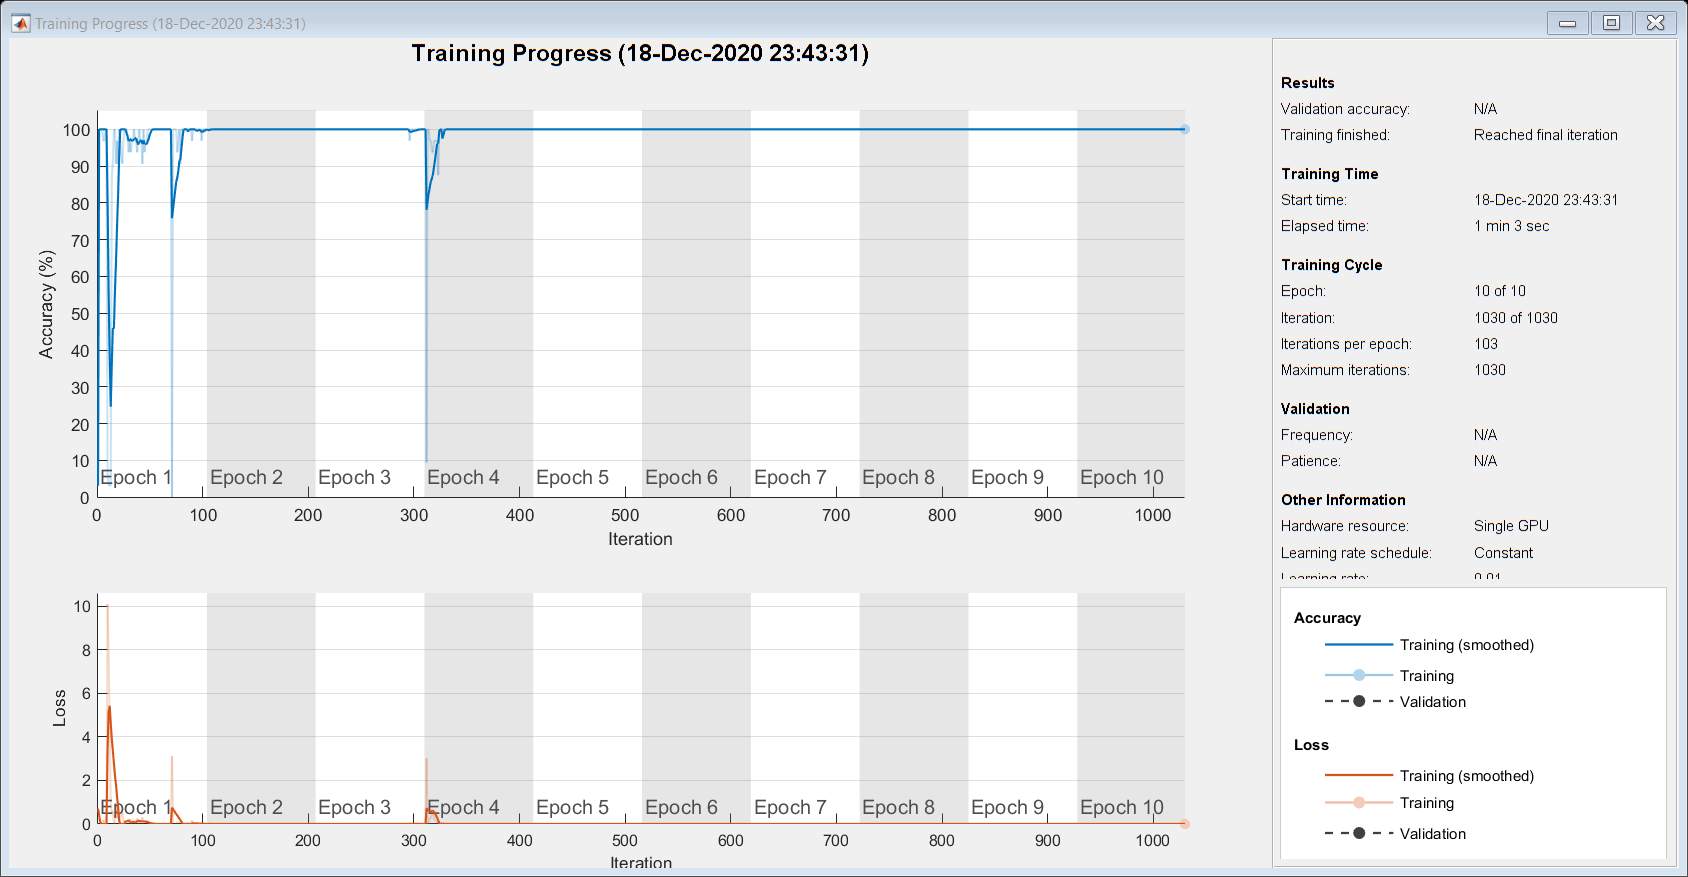

%
clear all;
minOneBeat = 150 * 1;
currentBeats = 1500;

%input = csvread('BioMetric_ECG_PPG_SQRT_MDPI_V1.csv',1,0);
input = csvread('BioMetric_ECG_PPG_SQRT_v1.csv',1,0);

% Rounding the decimal to integer
input = round(input);
valid_Usr = "Valid-User";
invalid_Usr = "Attacker";
numClasses = 2;

[rows,cols] = size(input);

i=1;
j=1;
k = 1;
usr = cols/3;
sample = round(rows/minOneBeat)-1;
loop = 1;
% k+2 mean taking SQRT dataset
for m = 1:usr
    for l = 1:sample
        if (rows > j+minOneBeat)
            trainingInput = input(j:j+minOneBeat-1,k+2)';
            XTrain_cell{loop,1} = trainingInput(1,:);

            if (m == 1)
                target2{loop,1} = valid_Usr;
                target3(loop,1) = valid_Usr;
            else
                target2{loop,1} = invalid_Usr;
                target3(loop,1) = invalid_Usr;
            end
            j = i * minOneBeat + 1 ;
            loop = loop + 1;
        end
    end
    k = i*3+1;
    j = 1;
    i = 1;
end


maxEpochs = 10 ;
initialLearnRate = 0.01;
miniBatchSize = 32;
fs = 100;
% instfreq and pentropy
numberOfFeatures = 2;

layers = [ ...
    sequenceInputLayer(numberOfFeatures)
    bilstmLayer(100,'OutputMode','last')
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer
    ];
options = trainingOptions('adam', ...
    'MaxEpochs',maxEpochs, ...
    'MiniBatchSize', miniBatchSize, ...
    'InitialLearnRate', initialLearnRate, ...
    'GradientThreshold', 1, ...
    'plots','training-progress', ...
    'Verbose',true);



    data = [XTrain_cell,target2];
    % Data partition (NON RANDOM) (train: 70%, test: 30%)
    
    PD = 0.30 ;  % 30% Test 70% train
    % Let P be your N-by-M input dataset
    % Solution-1 (need Statistics & ML Toolbox)
    %target1 = categorical(target1);
    cv = cvpartition(target3,'HoldOut',PD);
    dataTrainCombo = data(cv.training,:);
    dataTestCombo = data(cv.test,:);
    dataTrainTarget = dataTrainCombo(:,2);
    dataTrainTarget = string(dataTrainTarget);
    dataTrain = dataTrainCombo(:,1);
    dataTest = dataTestCombo(:,1);
    dataTestTarget = dataTestCombo(:,2);
    dataTestTarget = string(dataTestTarget);    
    
    dataTrain = cellfun(@(x)normalize(x)',dataTrain,'UniformOutput',false); 
    instfreqTrain1 = cellfun(@(x)instfreq(x,fs)',dataTrain,'UniformOutput',false);
    pentropyTrain1 = cellfun(@(x)pentropy(x,fs)',dataTrain,'UniformOutput',false);
    XTrain1_2 = cellfun(@(x,y)[x;y],instfreqTrain1,pentropyTrain1,'UniformOutput',false);
    
    XV1 = [XTrain1_2{:}];
    mu1 = mean(XV1,2);
    sg1 = std(XV1,[],2);
    XTrainSD = cellfun(@(x)(x-mu1)./sg1,XTrain1_2,'UniformOutput',false);
    
    net2 = trainNetwork(XTrainSD,categorical(dataTrainTarget),layers,options);    

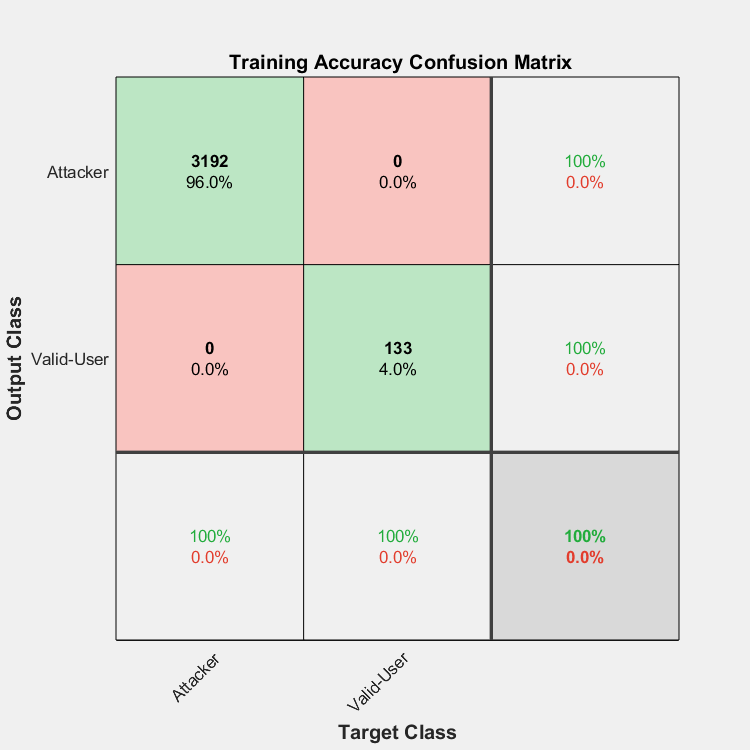

    txtTrain = ' Training Accuracy';
    txtTest = ' Testing Accuracy';
    
    trainPred = classify(net2,XTrainSD);
    catTrain = categorical(dataTrainTarget);
    figure;
    plotconfusion(categorical(dataTrainTarget'),trainPred',txtTrain);

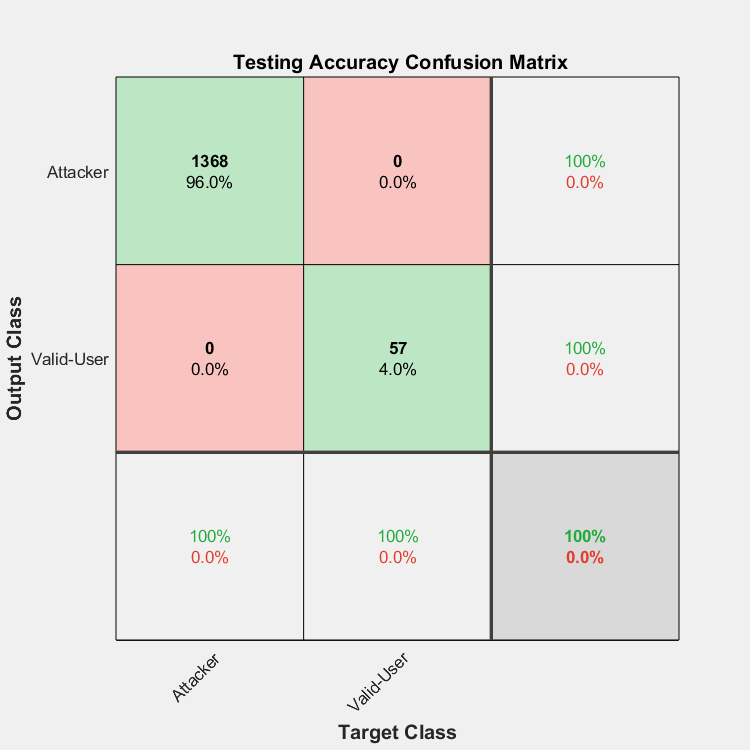

    
    %Normalize the data
    dataTest = cellfun(@(x)normalize(x)',dataTest,'UniformOutput',false);
    instfreqTest1 = cellfun(@(x)instfreq(x,fs)',dataTest,'UniformOutput',false);
    pentropyTest1 = cellfun(@(x)pentropy(x,fs)',dataTest,'UniformOutput',false);
    XTest1_2 = cellfun(@(x,y)[x;y],instfreqTest1,pentropyTest1,'UniformOutput',false);
    
    XV1 = [XTest1_2{:}];
    mu1 = mean(XV1,2);
    sg1 = std(XV1,[],2);
    XTestSD1_2 = cellfun(@(x)(x-mu1)./sg1,XTest1_2,'UniformOutput',false);
        
    testPred1 = classify(net2,XTestSD1_2);
    catTest = categorical(dataTestTarget);
    figure;
    plotconfusion(categorical(dataTestTarget'), testPred1', txtTest );